% Juan Jesús Ortiz

tinicial=0;      %proporciona el tiempo inicial
tfinal=15;  %proporciona el tiempo final
n=500;   % proporciona el número de iteraciones
h=0.03;     %calcula el tamaño de paso
t= tinicial:h:tfinal;  %define el vector t usando las variables anteriores
x(1)=0;     %proporciona el valor inicial del vector x

     for i=1:n % aplica el método de Euler:
          x(i+1) = (x(i)) + (h*(9.8*t(i)));   % calcula x(i+1) según la fórmula de Euler
      end
      
disp(['Vector t: ' num2str(t)])     %despliega el vector t

Vector t: 0         0.03         0.06         0.09         0.12         0.15         0.18         0.21         0.24         0.27          0.3         0.33         0.36         0.39         0.42         0.45         0.48         0.51         0.54         0.57          0.6         0.63         0.66         0.69         0.72         0.75         0.78         0.81         0.84         0.87          0.9         0.93         0.96         0.99         1.02         1.05         1.08         1.11         1.14         1.17          1.2         1.23         1.26         1.29         1.32         1.35         1.38         1.41         1.44         1.47          1.5         1.53         1.56         1.59         1.62         1.65         1.68         1.71         1.74         1.77          1.8         1.83         1.86         1.89         1.92         1.95         1.98         2.01         2.04         2.07          2.1         2.13         2.16         2.19         2.22         2.25         2.28 

disp(['Vector x (Euler): ' num2str(x)])    %despliega el vector x

Vector x (Euler): 0              0        0.00882        0.02646        0.05292         0.0882         0.1323        0.18522        0.24696        0.31752         0.3969         0.4851        0.58212        0.68796        0.80262         0.9261         1.0584        1.19952        1.34946        1.50822         1.6758         1.8522        2.03742        2.23146        2.43432          2.646         2.8665        3.09582        3.33396        3.58092         3.8367         4.1013        4.37472        4.65696        4.94802         5.2479         5.5566        5.87412        6.20046        6.53562         6.8796         7.2324        7.59402        7.96446        8.34372         8.7318         9.1287        9.53442        9.94896       10.37232        10.8045        11.2455       11.69532       12.15396       12.62142        13.0977        13.5828       14.07672       14.57946       15.09102        15.6114        16.1406       16.67862       17.22546       17.78112        18.3456      

plot(t,x)         % grafica la distancia respecto del tiempo
xreal= 4.9 * t.^2;       % calcula el vector xreal utilizando la función analítica
disp(['Vector xreal: ' num2str(xreal)]) %despliega en pantalla el vector de valores de la solución analítica (la solución matemática de la ecuación diferencial)

Vector xreal: 0        0.00441        0.01764        0.03969        0.07056        0.11025        0.15876        0.21609        0.28224        0.35721          0.441        0.53361        0.63504        0.74529        0.86436        0.99225        1.12896        1.27449        1.42884        1.59201          1.764        1.94481        2.13444        2.33289        2.54016        2.75625        2.98116        3.21489        3.45744        3.70881          3.969        4.23801        4.51584        4.80249        5.09796        5.40225        5.71536        6.03729        6.36804        6.70761          7.056        7.41321        7.77924        8.15409        8.53776        8.93025        9.33156        9.74169       10.16064       10.58841         11.025       11.47041       11.92464       12.38769       12.85956       13.34025       13.82976       14.32809       14.83524       15.35121         15.876       16.40961       16.95204       17.50329       18.06336       18.63225       19.

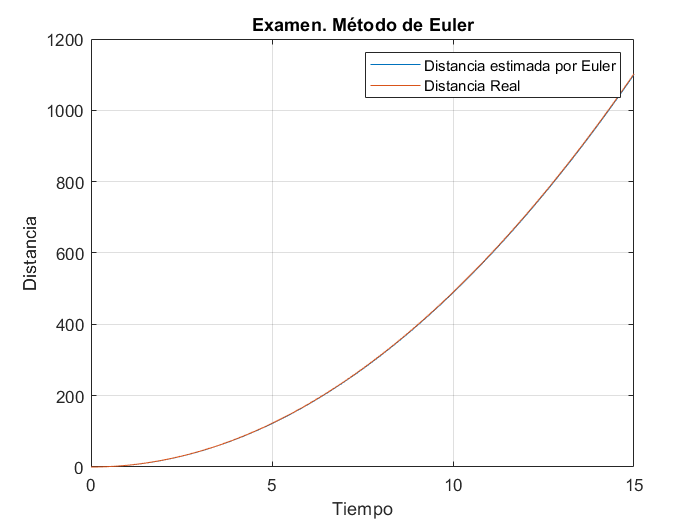

hold on               %la siguiente gráfica no borrará la anterior
plot(t,xreal)         % grafica x yreal
xlabel('Tiempo')           % se pone nombre al eje horizontal
ylabel('Distancia')           % se pone nombre el eje vertical
grid on               % se pinta el grid en la gráfica
legend('Distancia estimada por Euler','Distancia Real')   % se pone el una referencia a cada gráfica para identificarlas
title('Examen. Método de Euler')   %se pone el título del gráfico